clear;
close all;

excludeSubjects();

ans =   Map with properties:

        Count: 45
      KeyType: char
    ValueType: any


%add nice things to path
addpath('D:\Documents\software\cbrewer') %for color
[cb] = cbrewer('qual','Set1',10,'pchip');

N=length(subjects)

N = 49

[Det_diff,Dis_diff,Tilt_diff] = deal(nan(N,1));
[Det_ts,Dis_ts,Tilt_ts] = deal(nan(N,1));


for s=which_subjects
        
    subject = data_struct(participants.name_initials{s});
    

        confC = subject.DisConf(subject.DisResp==1 & subject.DisInclude==1);
        confA = subject.DisConf(subject.DisResp==0 & subject.DisInclude==1);
        
        Dis_diff(s) = mean(confC)-mean(confA);
        [h,p,ci,stats]=ttest2(confC,confA);
        Dis_ts(s) =stats.tstat;
        
        confY = subject.DetConf(subject.DetResp==1 & subject.DetInclude==1);
        confN = subject.DetConf(subject.DetResp==0 & subject.DetInclude==1);
        
        Det_diff(s) = mean(confY)-mean(confN);
        [h,p,ci,stats]=ttest2(confY,confN);
        Det_ts(s) =stats.tstat;
        
        confT = subject.TiltConf(subject.TiltResp==1 & subject.TiltInclude==1);
        confV = subject.TiltConf(subject.TiltResp==0 & subject.TiltInclude==1);
       
        Tilt_diff(s) = mean(confT)-mean(confV);
        [h,p,ci,stats]=ttest2(confT,confV);
        Tilt_ts(s) =stats.tstat;
        
end

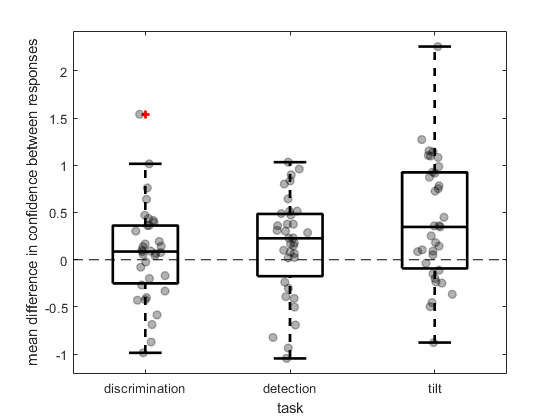

noise1 = normrnd(0,0.05,1,N);
noise2 = normrnd(0,0.05,1,N);
noise3 = normrnd(0,0.05,1,N);

figure; hold on;
h=boxplot([Dis_diff Det_diff Tilt_diff],'Colors','k');
set(h,{'linew'},{2})
% plot([ones(1,35)+noise1; 2*ones(1,35)+noise2],[meanAccDis;meanAccDet],'color',[0.5,0.5,0.5]);
scatter(ones(N,1)+noise1',Dis_diff,'MarkerEdgeColor','k','MarkerFaceColor',...
    [0,0,0],'LineWidth',1, 'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
scatter(2*ones(N,1)+noise2',Det_diff,'MarkerEdgeColor','k','MarkerFaceColor',...
    [0,0,0],'LineWidth',1,'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
scatter(3*ones(N,1)+noise2',Tilt_diff,[],'MarkerEdgeColor','k','MarkerFaceColor',...
    [0,0,0],'LineWidth',1,'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
ylabel('mean difference in confidence between responses');

xlim([0.5,3.5]); xlabel('task');
% ylim([0.4,1]);
plot([0.5,3.5],[0,0],'k--')
set(gca,'xtick',[1:3],'xticklabel',{'discrimination','detection','tilt'})
fig = gcf;
s=hgexport('readstyle','presentation');
s.Format = 'png';
s.Width = 12;
s.Height = 10;
hgexport(fig,'figures/conf_diff',s);

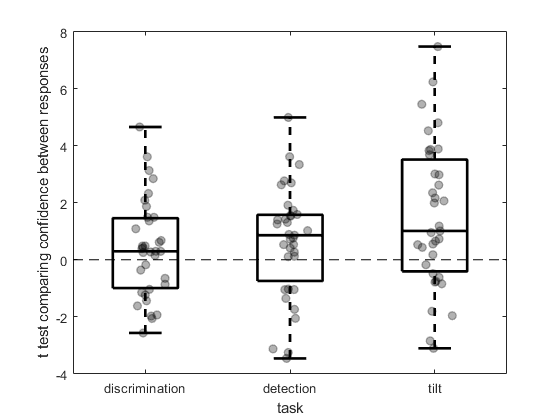

figure; hold on;
h=boxplot([Dis_ts Det_ts Tilt_ts],'Colors','k');
set(h,{'linew'},{2})
% plot([ones(1,35)+noise1; 2*ones(1,35)+noise2],[meanAccDis;meanAccDet],'color',[0.5,0.5,0.5]);
scatter(ones(N,1)+noise1',Dis_ts,'MarkerEdgeColor','k','MarkerFaceColor',...
    [0,0,0],'LineWidth',1, 'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
scatter(2*ones(N,1)+noise2',Det_ts,'MarkerEdgeColor','k','MarkerFaceColor',...
    [0,0,0],'LineWidth',1,'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
scatter(3*ones(N,1)+noise2',Tilt_ts,[],'MarkerEdgeColor','k','MarkerFaceColor',...
    [0,0,0],'LineWidth',1,'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
ylabel('t test comparing confidence between responses');

xlim([0.5,3.5]); xlabel('task');
% ylim([0.4,1]);
plot([0.5,3.5],[0,0],'k--')
set(gca,'xtick',[1:3],'xticklabel',{'discrimination','detection','tilt'})
fig = gcf;
s=hgexport('readstyle','presentation');
s.Format = 'png';
s.Width = 12;
s.Height = 10;
hgexport(fig,'figures/conf_diff_t',s);

region = 'FPm'

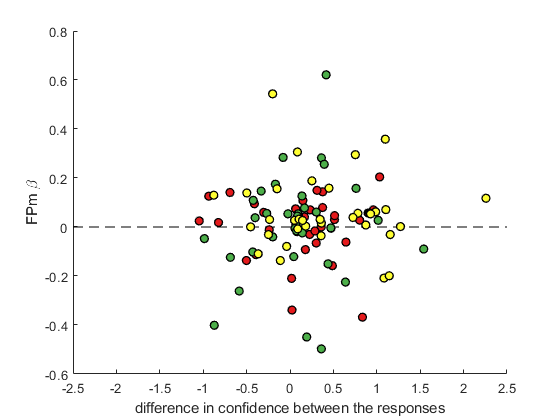

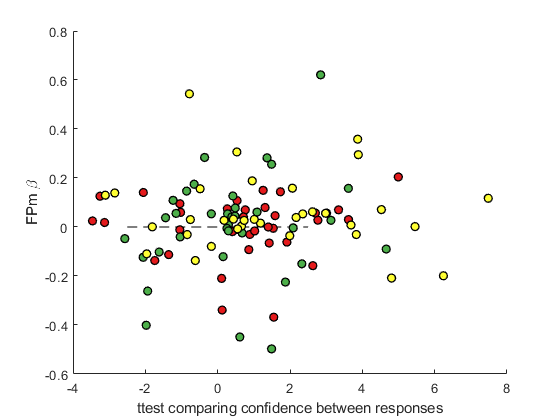

region = 'FPl'

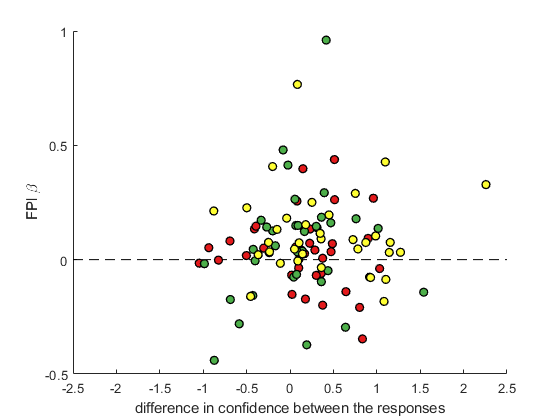

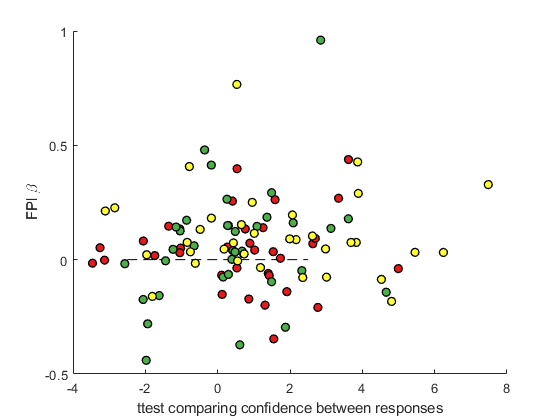

region = 'BA46'

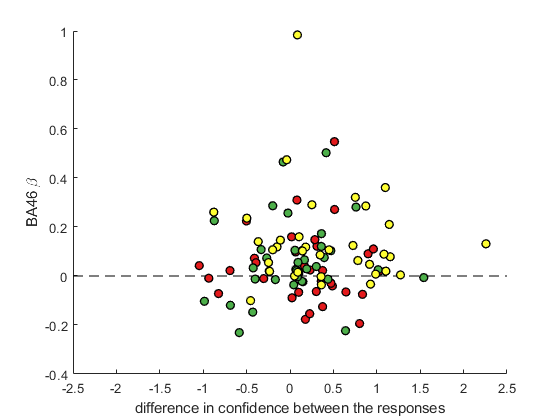

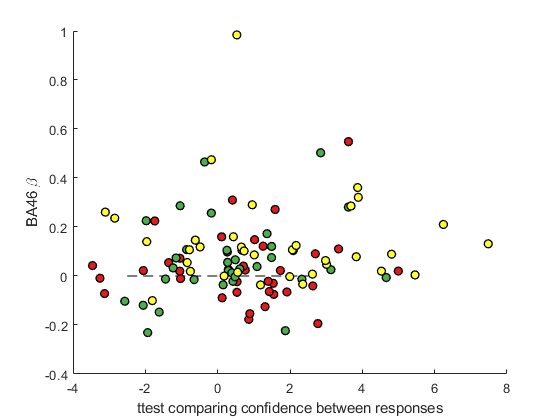

region = 'vmPFC'

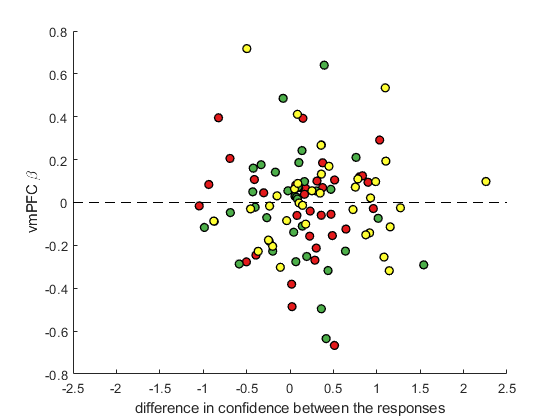

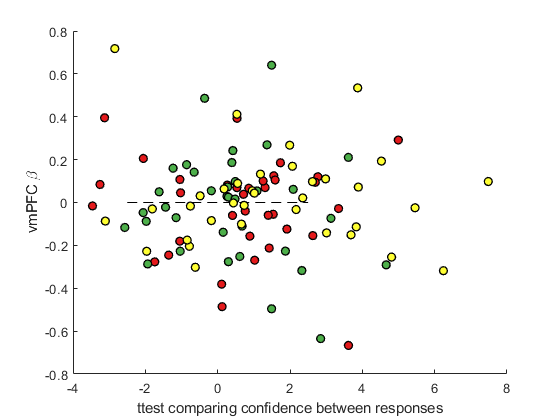

region = 'rSTS'

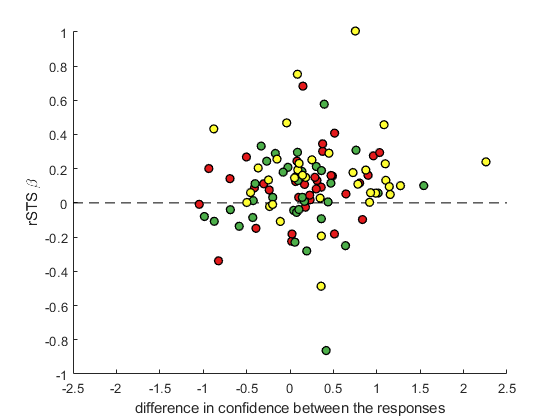

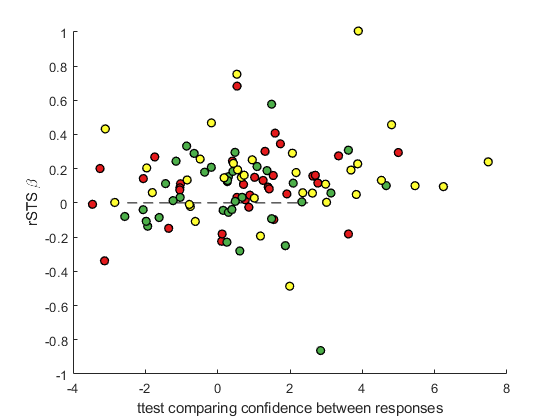

region = 'preSMA'

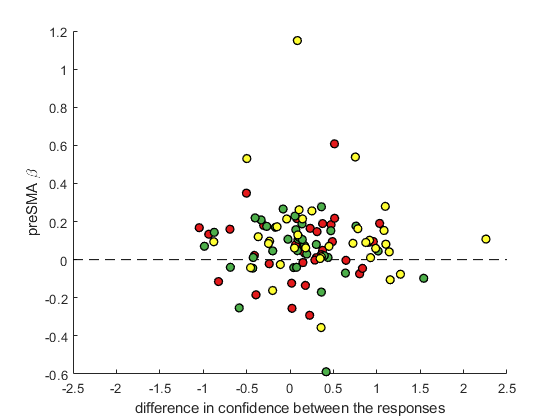

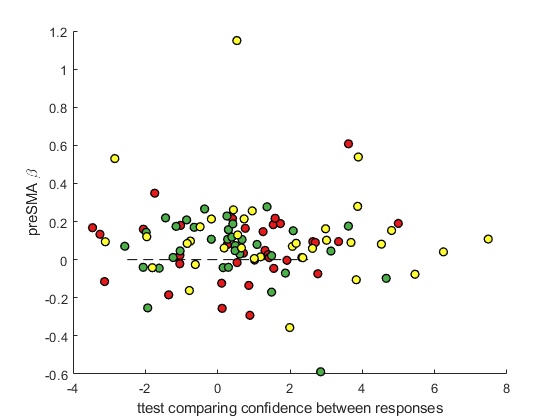

region = 'rTPJ'

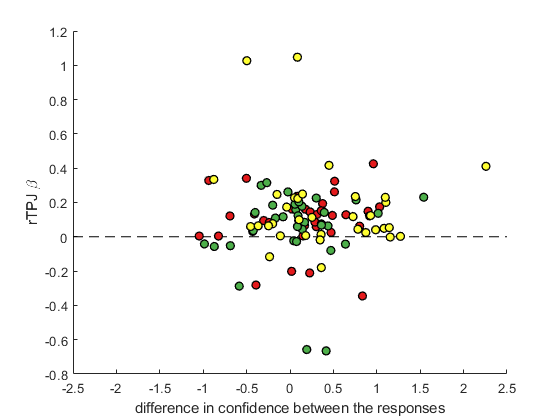

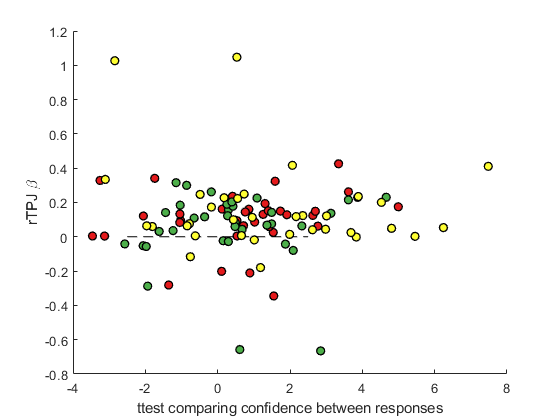

regions = {'FPm','FPl','BA46','vmPFC','rSTS','preSMA','rTPJ'};

for i = 1:length(regions) 
    region = regions{i}
    DetSq = load(fullfile('..','analyzed','DM1555','group','confSqDet',[region,'.mat']));
    DisSq = load(fullfile('..','analyzed','DM1555','group','confSqDis',[region,'.mat']));
    TiltSq = load(fullfile('..','analyzed','DM1555','group','confSqTilt',[region,'.mat']));
    
    fig=figure; hold on;
    plot([-2.5,2.5],[0,0],'k--')
    % plot([abs(log2(DisSlopes(which_subjects))), ...
    %     abs(log2(DetSlopes(which_subjects))), ...
    %     abs(log2(TiltSlopes(which_subjects)))]', ...
    %     [DisSq.ROI_vec, DetSq.ROI_vec, TiltSq.ROI_vec]', 'k');
    scatter(Det_diff(which_subjects),DetSq.ROI_vec,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
    scatter(Dis_diff(which_subjects),DisSq.ROI_vec,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(3,:),'LineWidth',1);
    scatter(Tilt_diff(which_subjects),TiltSq.ROI_vec,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(7,:),'LineWidth',1);
    xlabel('difference in confidence between the responses');
    ylabel([region, ' \beta']);
    hgexport(fig,['figures/conf_diff_',region],s);
    
    fig=figure; hold on;
    plot([-2.5,2.5],[0,0],'k--')
    % plot([abs(log2(DisSlopes(which_subjects))), ...
    %     abs(log2(DetSlopes(which_subjects))), ...
    %     abs(log2(TiltSlopes(which_subjects)))]', ...
    %     [DisSq.ROI_vec, DetSq.ROI_vec, TiltSq.ROI_vec]', 'k');
    scatter(Det_ts(which_subjects),DetSq.ROI_vec,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
    scatter(Dis_ts(which_subjects),DisSq.ROI_vec,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(3,:),'LineWidth',1);
    scatter(Tilt_ts(which_subjects),TiltSq.ROI_vec,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(7,:),'LineWidth',1);
    xlabel('ttest comparing confidence between responses');
    ylabel([region, ' \beta']);
    hgexport(fig,['figures/conf_t_',region],s);
    
    
end

regions = {'FPm','FPl','BA46','vmPFC','rSTS','preSMA','rTPJ'};
meanDiffs = mean(abs([Det_diff Dis_diff Tilt_diff]),2)

meanDiffs =        NaN
    0.4889
    0.4797
    0.1626
       NaN
    0.5764
    0.2960
    1.3433
       NaN
    0.4301


mean_ts = mean(abs([Det_ts Dis_ts Tilt_ts]),2)

mean_ts =        NaN
    1.6893
    1.3598
    0.8390
       NaN
    1.5081
    1.4319
    4.3016
       NaN
    1.5067


region = 'FPm'

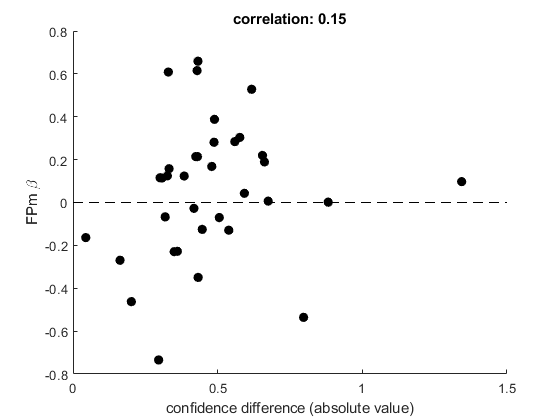

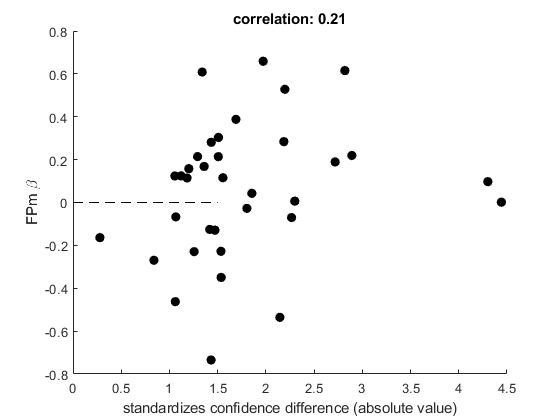

region = 'FPl'

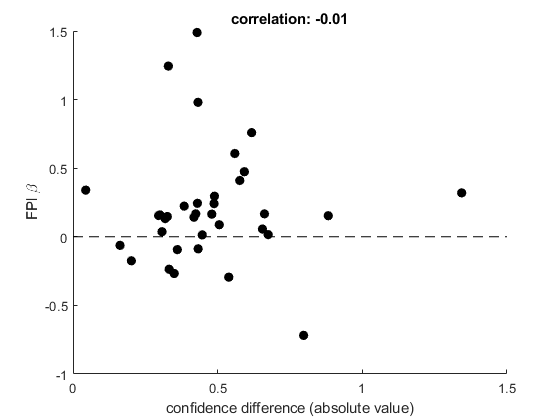

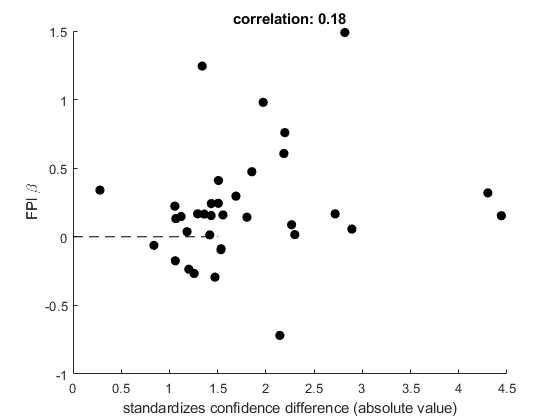

region = 'BA46'

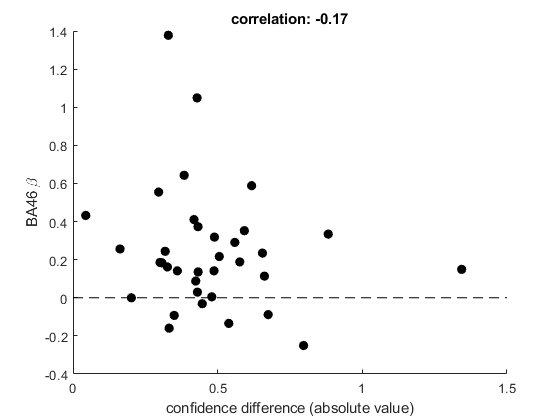

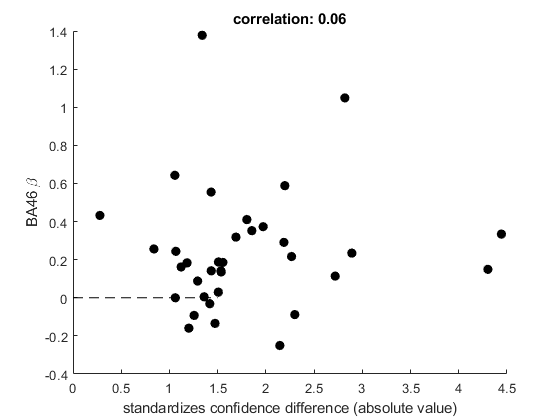

region = 'vmPFC'

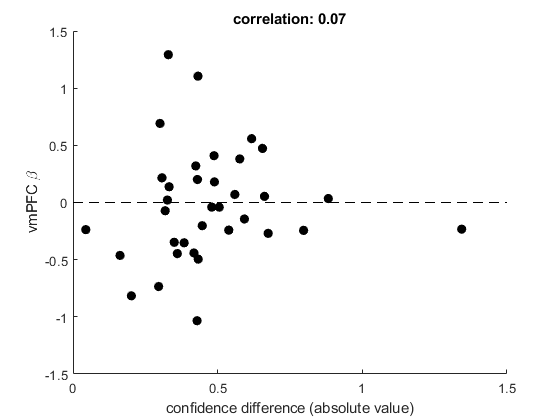

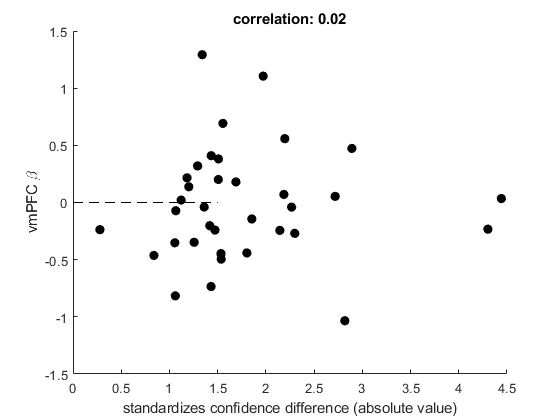

region = 'rSTS'

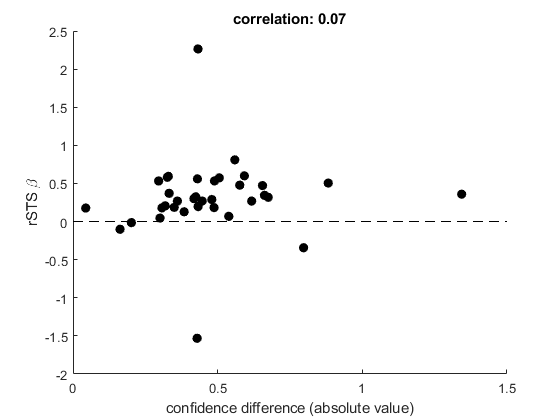

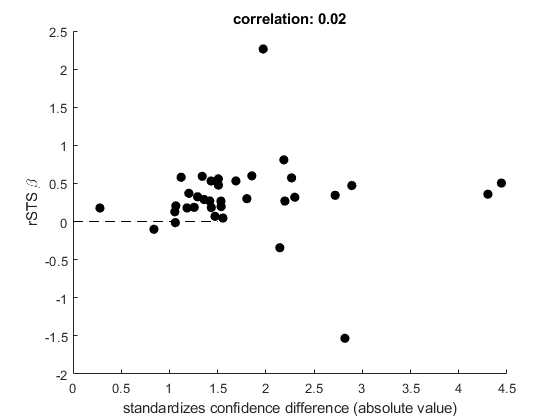

region = 'preSMA'

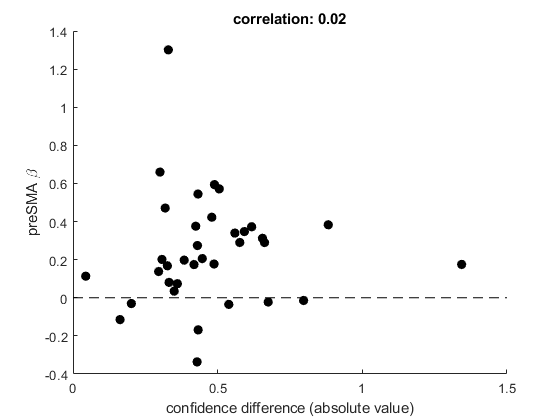

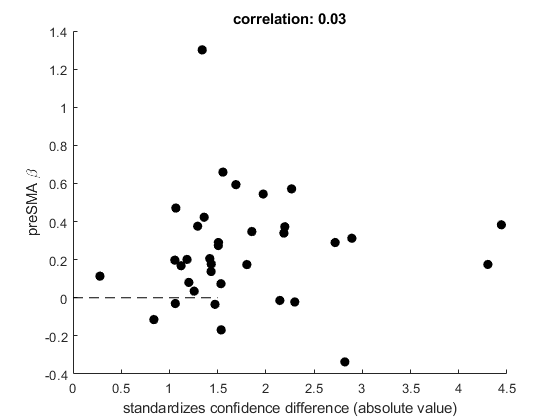

region = 'rTPJ'

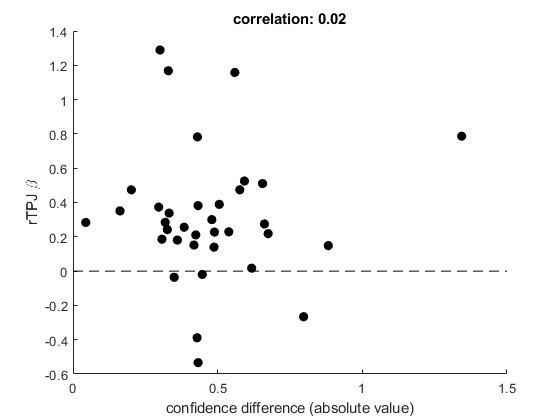

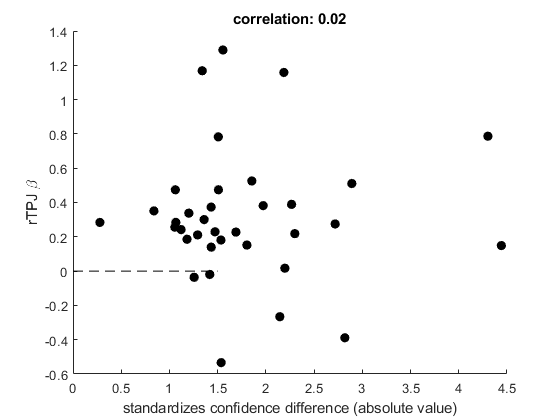


for i = 1:length(regions) 
    region = regions{i}
    Sq = load(fullfile('..','analyzed','DM1555','group','confSq',[region,'.mat']));
    fig=figure; hold on;
    plot([0,1.5],[0,0],'k--')
    % plot([abs(log2(DisSlopes(which_subjects))), ...
    %     abs(log2(DetSlopes(which_subjects))), ...
    %     abs(log2(TiltSlopes(which_subjects)))]', ...
    %     [DisSq.ROI_vec, DetSq.ROI_vec, TiltSq.ROI_vec]', 'k');
    scatter(meanDiffs(which_subjects),Sq.ROI_vec,[],'MarkerEdgeColor','k','MarkerFaceColor','k','LineWidth',1);
    title(sprintf('correlation: %0.2f',corr(meanDiffs(which_subjects),Sq.ROI_vec)));
%     scatter(abs(log2(DisSlopes(which_subjects))),DisSq.ROI_vec,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(3,:),'LineWidth',1);
%     scatter(abs(log2(TiltSlopes(which_subjects))),TiltSq.ROI_vec,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(7,:),'LineWidth',1);
    xlabel('confidence difference (absolute value)');
    ylabel([region, ' \beta']);
    hgexport(fig,['figures/conf_diff_',region],s);
    
    
    fig=figure; hold on;
    plot([0,1.5],[0,0],'k--')
    % plot([abs(log2(DisSlopes(which_subjects))), ...
    %     abs(log2(DetSlopes(which_subjects))), ...
    %     abs(log2(TiltSlopes(which_subjects)))]', ...
    %     [DisSq.ROI_vec, DetSq.ROI_vec, TiltSq.ROI_vec]', 'k');
    scatter(mean_ts(which_subjects),Sq.ROI_vec,[],'MarkerEdgeColor','k','MarkerFaceColor','k','LineWidth',1);
    title(sprintf('correlation: %0.2f',corr(mean_ts(which_subjects),Sq.ROI_vec)));

%     scatter(abs(log2(DisSlopes(which_subjects))),DisSq.ROI_vec,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(3,:),'LineWidth',1);
%     scatter(abs(log2(TiltSlopes(which_subjects))),TiltSq.ROI_vec,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(7,:),'LineWidth',1);
    xlabel('standardizes confidence difference (absolute value)');
    ylabel([region, ' \beta']);
    hgexport(fig,['figures/conf_t_',region],s);
end

Fit mixed linear model

s = nominal(repmat((1:35)',3,1));
task = nominal(repelem((1:3)',35,1));
diff = abs([Dis_diff(which_subjects); Det_diff(which_subjects); Tilt_diff(which_subjects)]);
ps = [];
for i = 1:length(regions) 
    region = regions{i}
    DetSq = load(fullfile('..','analyzed','DM1555','group','confSqDet',[region,'.mat']));
    DisSq = load(fullfile('..','analyzed','DM1555','group','confSqDis',[region,'.mat']));
    TiltSq = load(fullfile('..','analyzed','DM1555','group','confSqTilt',[region,'.mat']));
    beta = [DisSq.ROI_vec; DetSq.ROI_vec; TiltSq.ROI_vec];

    tbl = table(s,task,diff,beta,'VariableNames',{'s','task','diff','beta'});
    lme = fitlme(tbl,'beta~diff+(1|s)+(diff-1|s)');
    ps(end+1) = lme.coefTest;
end

region = 'FPm'

region = 'FPl'

region = 'BA46'

region = 'vmPFC'

region = 'rSTS'

region = 'preSMA'

region = 'rTPJ'

s = nominal(repmat((1:35)',3,1));
task = nominal(repelem((1:3)',35,1));
t = abs([Dis_ts(which_subjects); Det_ts(which_subjects); Tilt_ts(which_subjects)]);
ps = [];
for i = 1:length(regions) 
    region = regions{i}
    DetSq = load(fullfile('..','analyzed','DM1555','group','confSqDet',[region,'.mat']));
    DisSq = load(fullfile('..','analyzed','DM1555','group','confSqDis',[region,'.mat']));
    TiltSq = load(fullfile('..','analyzed','DM1555','group','confSqTilt',[region,'.mat']));
    beta = [DisSq.ROI_vec; DetSq.ROI_vec; TiltSq.ROI_vec];

    tbl = table(s,task,t,beta,'VariableNames',{'s','task','t','beta'});
    lme = fitlme(tbl,'beta~t+(1|s)+(t-1|s)');
    ps(end+1) = lme.coefTest;
end

region = 'FPm'

region = 'FPl'

region = 'BA46'

region = 'vmPFC'

region = 'rSTS'

region = 'preSMA'

region = 'rTPJ'